clc
clear
close all

precision = input('Target RELATIVE precision for CI half-width (e.g., 1e-3): ');

useRelativeTol = true;     % set false to use absolute MOE <= precision instead

z = 1.96;                  % for 95% confidence interval

pi_es  = 4;                % current estimate 
numerator = 0;             % number of batches processed
max_steps = 1e5;           % max cap on batches

cx = 0.5; cy = 0.5;
r  = 0.5; r2 = r^2;

N = 10000;                 % batch size per iteration

hits_total = 0;
N_total    = 0;

X = zeros(2, N);
k = false(1, N);

met = false;            % becomes true when CI criterion is satisfied
while ~met && (numerator < max_steps)

    numerator = numerator + 1;

    X = rand(2, N);

    D2 = (X(1,:)-cx).^2 + (X(2,:)-cy).^2;
    k =(D2 <= r2);

    hits_batch = nnz(k);
    hits_total = hits_total + hits_batch;
    N_total    = N_total + N;

    p_hat  = hits_total / N_total;    % success prob for "inside circle"
    pi_es  = p_hat / r2;              % 4*pi/4

    se_pi  = sqrt(p_hat * (1 - p_hat) / N_total) / r2; % Standard error of pi_hat

    % Margin of error (half-width of CI)
    moe = z * se_pi;

    % Stopping criterion: CI half-width small enough
    if useRelativeTol
        rel_moe = moe / max(pi_es, eps);  % relative half-width
        met = (rel_moe <= precision);
    else
        met = (moe <= precision);         % absolute half-width
    end

end

% ------------------- Report final results -------------------
fprintf('Final estimate: pi ≈ %.10f\n', pi_es);

Final estimate: pi ≈ 3.1402415094


fprintf('Batches used: %d (batch size N=%d, total points = %d)\n', ...
        numerator, N, N_total);

Batches used: 106 (batch size N=10000, total points = 1060000)


fprintf('95%% CI half-width (MOE) = %.3e; relative = %.3e\n', ...
        moe, moe/max(pi_es,eps));

95% CI half-width (MOE) = 3.128e-03; relative = 9.961e-04


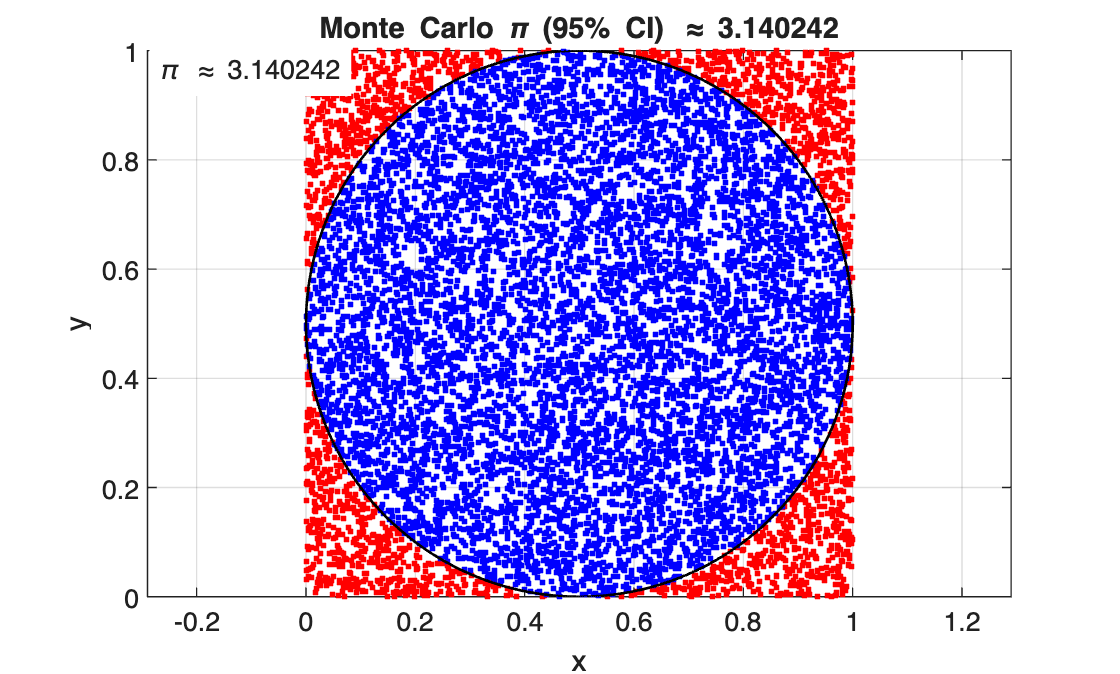

figure;
plot(X(1, ~k), X(2, ~k), '.r');   % outside the circle
hold on
plot(X(1,  k), X(2,  k), '.b');   % inside the circle

theta = linspace(0, 2*pi, 400);
plot(cx + r*cos(theta), cy + r*sin(theta), 'k-', 'LineWidth', 1.0)

xlim([0 1]); ylim([0 1]); axis equal
xlabel('x'); ylabel('y'); grid on
title(sprintf('Monte Carlo \\pi (95%% CI) \\approx %.6f', pi_es));

% Stamp CI info on the plot
txt = {sprintf('\\pi \\approx %.6f', pi_es)};
text(0.01, 0.99, txt, 'Units','normalized', 'VerticalAlignment','top', ...
     'BackgroundColor','w');

hold off